clear all
close all
clc

rng(1);

load('dataBenchmark')



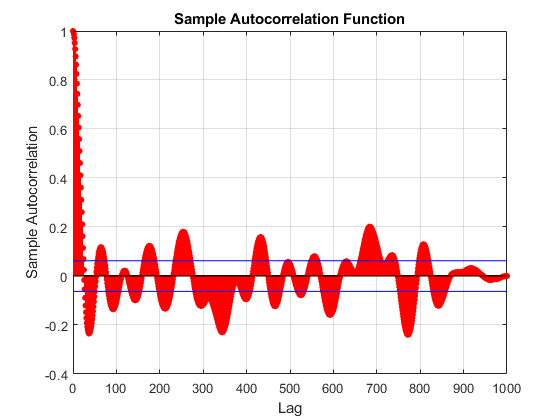


% plot(uEst)
% plot(yEst)
% for i =1:7
% uEst = [uEst ;(uEst+0.0*rand(size(uEst)))];
% yEst = [yEst ;(yEst+0.5*rand(size(yEst)))];
% end
% 
% yEst(yEst>10)=10;
% plot(uVal)
% plot(yVal)

autocorr(uEst,1000)

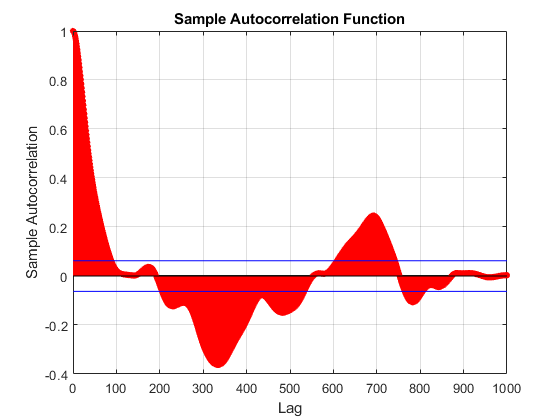

autocorr(yEst,1000)


% parcorr(uEst,1000)
% parcorr(yEst,1000)

Preprocessing Data

input = uEst/7 ;
output = yEst/14;

tinput = uVal/7 ;
toutput = yVal/14;

inlags=[1];
% inlags=[1 2 3 4];
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-990:end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-990:end-inlags(l));
end

outlags=[0 1 2 4 8 16];
% outlags=[0 1 2 3 4];
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-990:end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-990:end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);



% histogram(featurez(:,1),100)
% 
% inters = 0:0.005:0.995;
% for s = 1:200
% groupz{s} = (featurez(:,1)>= inters(s) & featurez(:,1)< inters(s)+0.005);
% end
% 
% sampled = [];
% sampledzeta= [];
% for s = 1:200
%     if ~isempty(featurez(groupz{s},:))      
% [sam,idx] = datasample(featurez(groupz{s},:),40,1);
% sampled = [sampled ; sam];
% zet = zeta(groupz{s});
% sampledzeta =  [sampledzeta ; zet(idx')];
%     end
% end
% 
% 
% histogram(sampled(:,1),200);
% histogram(sampledzeta(:,1),200);

% 
% featurez = sampled;
% zeta = sampledzeta;


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                 %degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 0.030029


Optimize TT cores

lambda=1*10^-3 ;
gamma=0;

difforder=2;
MAXITR = 2*d;

rez = [];
% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);

    "iteration:"    "1"    "0.053379"

    "iteration:"    "2"    "0.088487"

    "iteration:"    "3"    "0.11474"

    "iteration:"    "4"    "0.12857"

    "iteration:"    "5"    "0.14108"

    "iteration:"    "6"    "0.15596"

    "iteration:"    "7"    "0.17097"

    "iteration:"    "8"    "0.18325"

    "iteration:"    "9"    "0.19546"

    "iteration:"    "10"    "0.21349"

    "iteration:"    "11"    "0.22548"

    "iteration:"    "12"    "0.2393"

    "iteration:"    "13"    "0.25391"

    "iteration:"    "14"    "0.27164"



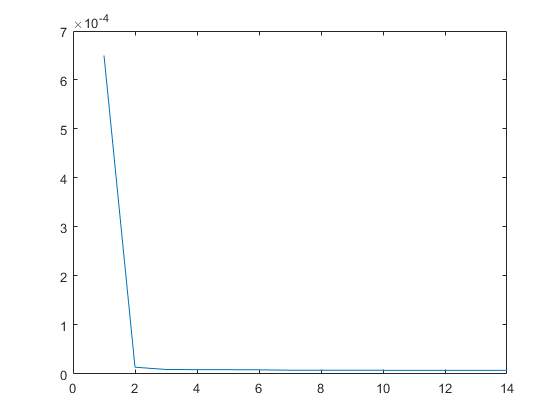

rez = [rez res1];


plot(res1)

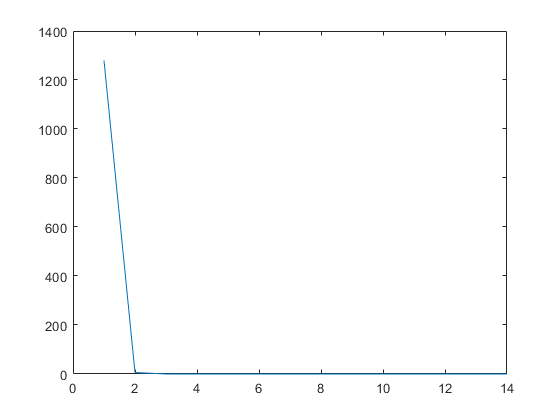

plot(res2)


trainerror = res1(end)

trainerror = 7.4092e-06


plot(rez)

Evaluate Test data

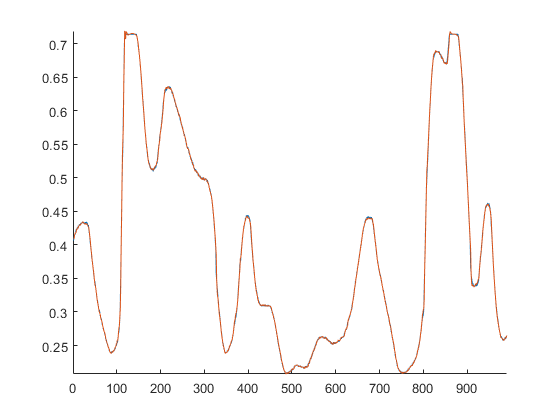


yhattrain  = evalspline(TN,featurez,n,m);

figure;
hold on
plot(zeta)
plot(yhattrain)
hold off
axis([0 inf -inf inf]);


erboiz = (yhattrain-zeta);
VAF = 1-var(erboiz)/var(zeta)

VAF = 0.9997

MSE = immse(yhattrain,zeta)

MSE = 7.4092e-06


yhat = evalspline(TN,tfeaturez,n,m);


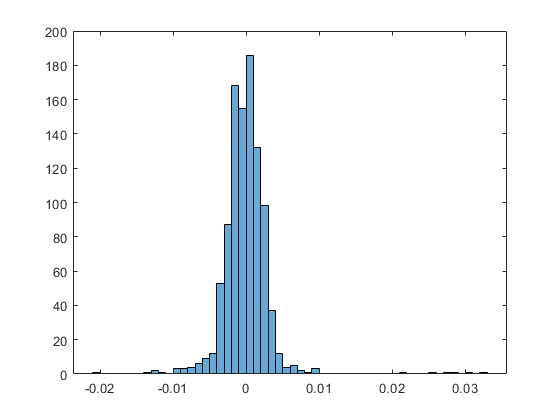


erboi = (yhat-yt);
histogram((erboi)');

VAF = 1-var(erboi)/var(yt)

VAF = 0.9995

MSE = immse(yhat,yt)

MSE = 1.1259e-05

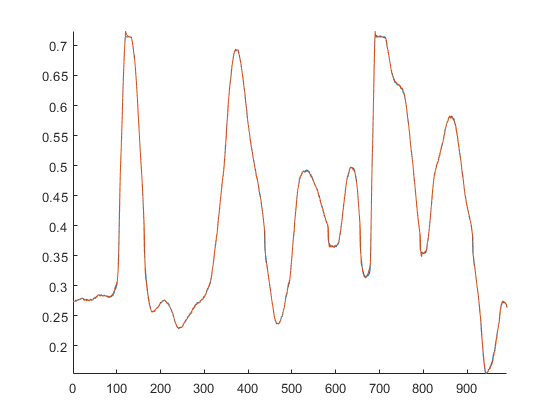


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

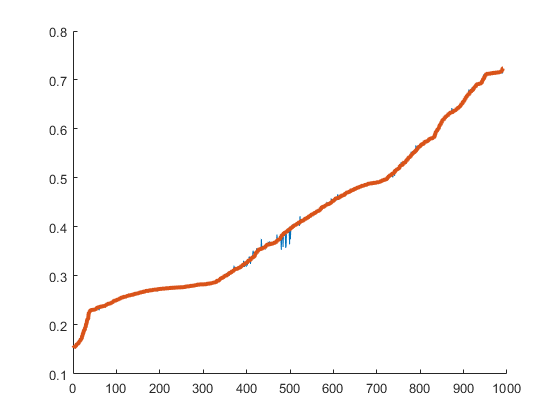


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

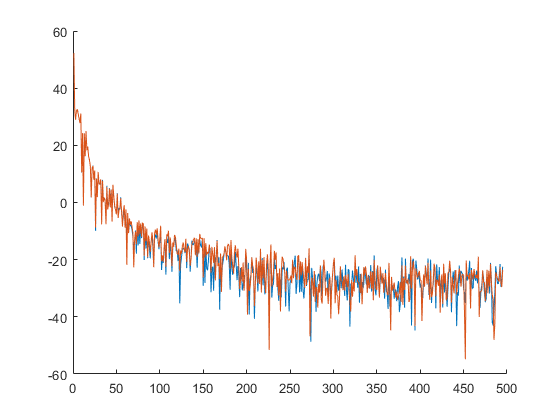


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FZ(1:floor(end/2)))
plot(FY(1:floor(end/2)))
hold off

% simfeaturez = tfeaturez;
% 
% for j = 1:3
% y_k = evalspline(TN,simfeaturez,n,m);
% 
% for k = 5:-1:2
% simfeaturez(k:end,k) = simfeaturez((k-1):end-1,(k-1));
% end
% simfeaturez(2:end,1) = y_k(1:end-1);
% 
% end
% 
% ysim = simfeaturez(4:end,1);
% 
% figure
% hold on
% plot(yt(2:end-2))
% plot(ysim)
% hold off
% axis([0 inf -inf inf])
% 
% VAF = 1-var(yt(2:end-2)-ysim)/var(yt)
% MSE = immse(10*yt(2:end-2),10*ysim)
% 
% 
% FY = mag2db(abs(fft(simfeaturez(3:end,1))));
% FZ = mag2db(abs(fft(yt)));
% 
% % heatmap(simfeaturez)
% % imagesc(simfeaturez)
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off

% plot(tinput)
% plot(toutput)

siminput = tinput;
simoutput = toutput;
numz = numel(outlags)

numz = 6

for j = 17:1024
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-outlags(2:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

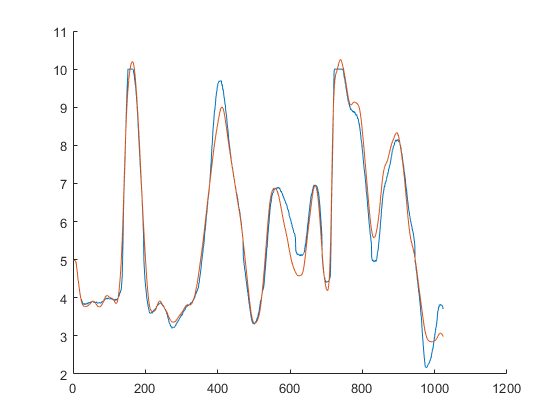


% siminput = tinput;
% simoutput = toutput;
% numz = numel(outlags);
% for j = 10:1000
% simfeaturez = [simoutput(j+numz-1:-1:j+1)' siminput(j+numz-1:-1:j+1)'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
% simoutput(j+numz) = evalspline(TN,simfeaturez,n,m);
% end

figure
hold on
plot(14*toutput)
plot(14*simoutput)
hold off


RMSE = sqrt(immse(14*toutput,14*simoutput))

RMSE = 0.3653

% simfeaturez = tfeaturez;
% simfeaturez(boolean(eye(9)))
% 
% diag(ones(1,5),-1)
% 
% ones(5,2)